Textfile = load("STM32Output.txt")

Textfile =    11.4900
    0.8400
    1.9200
    1.2700
    2.4500
   44.3800
   10.8200
    5.0200
    4.7700
    3.7000


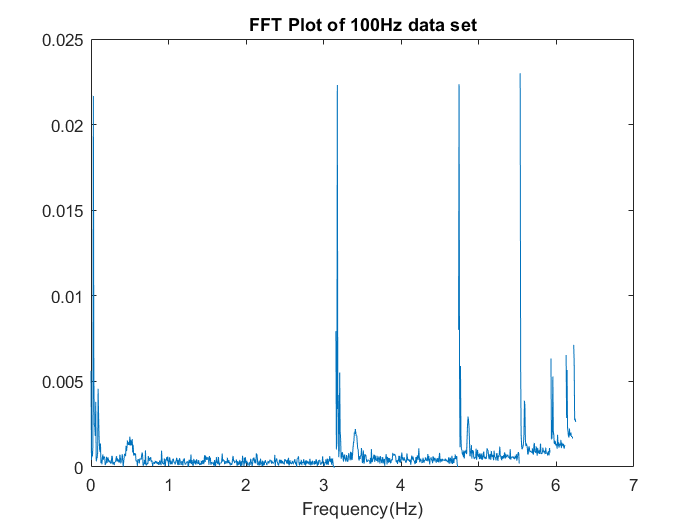

writematrix(Textfile, "STM32Output.csv");
FFTData = readtable("STM32Output.csv");


N =  2048 - 1; 
FFTData = FFTData{:, 1}/N; %data is symmetric, *2 to account for contribution of other half 
fs = 12.5;
frequency = fs*(0:(N/2))/N;

plot(frequency(1:1024), FFTData(1:1024)); %only plotting the real side of the dataset 
title("FFT Plot of 100Hz data set");
xlabel("Frequency(Hz)");